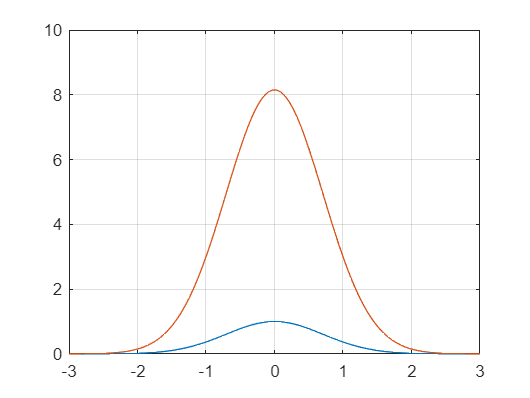

clear
t = linspace(-3,3,100);
y1 = exp(-t.*t);
y2 = 3*exp(1) * exp(-t.*t);
plot(t,y1)
grid on
hold on
plot(t, y2);

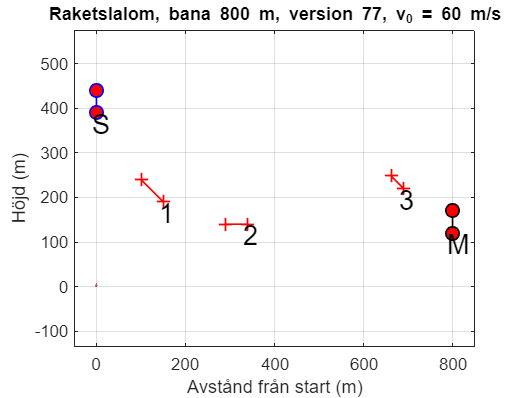

clear
load bana800-77.mat
plotTrack(portx, porty, ver, v1)

c = 0.25;
g = 9.82;
km = 2000;
alpha = 0;
m1 = 40;

t = linspace(0, 800, 100);
y = 400 - t/3

y =   400.0000  397.3064  394.6128  391.9192  389.2256  386.5320  383.8384  381.1448  378.4512  375.7576  373.0640  370.3704  367.6768  364.9832  362.2896  359.5960  356.9024  354.2088  351.5152  348.8215  346.1279  343.4343  340.7407  338.0471  335.3535  332.6599  329.9663  327.2727  324.5791  321.8855  319.1919  316.4983  313.8047  311.1111  308.4175  305.7239  303.0303  300.3367  297.6431  294.9495  292.2559  289.5623  286.8687  284.1751  281.4815  278.7879  276.0943  273.4007  270.7071  268.0135


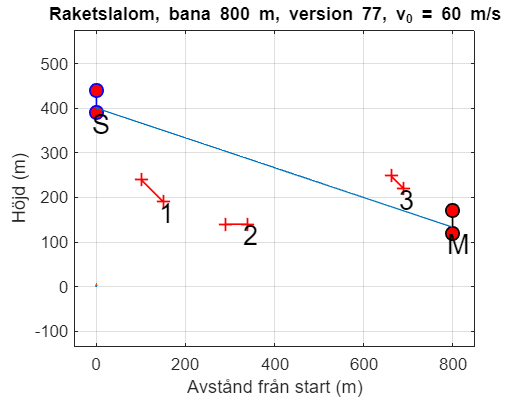

hold on
plot(t,y)

hold off

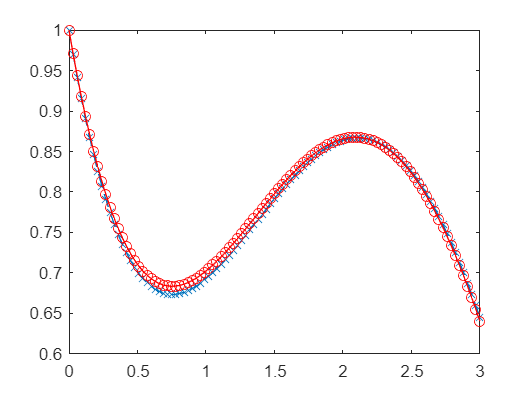

clf
clear
tspan = [0,3];
n = 100;
y1 = 1;
[t, y] = minEuler(@funkEx1, tspan, y1, n);
plot(t, y, 'x--');

ye = sin(t)/2 - cos(t)/2 + 3 * exp(-t)/2;
hold on
plot(t, ye, 'r-o')

clear
hold off

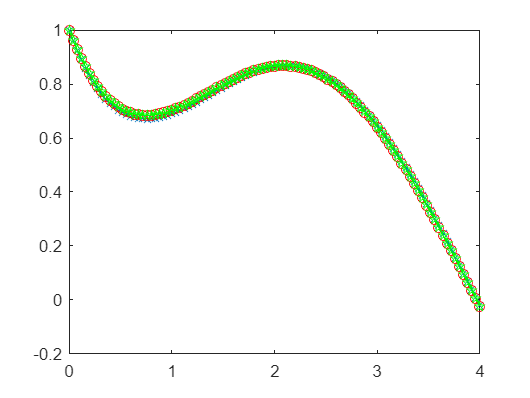

tspan = [0,4];
n = 100;
ybv = 1;
[~, y1] = minEuler(@funkEx2, tspan, ybv, n);
[~, y2] = minRK2(@funkEx2, tspan, ybv, n);
[t, y3] = minRK4(@funkEx2, tspan, ybv, n);
plot(t, y1, 'x--');

ye = sin(t)/2 - cos(t)/2 + 3 * exp(-t)/2;
hold on
plot(t, y2, 'r-o')
plot(t, y3, 'g-p')
hold off

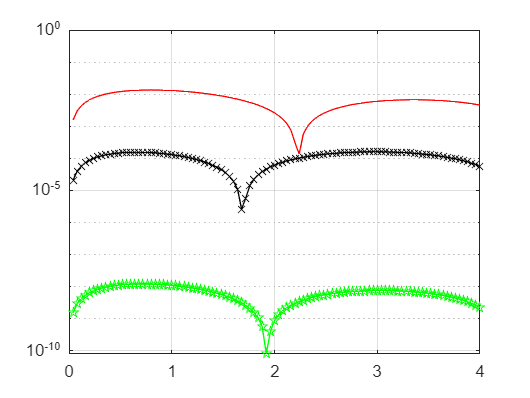

clf
semilogy(t, abs(y1-ye), 'r')
hold on
grid on
semilogy(t, abs(y2-ye), 'k-x')
semilogy(t, abs(y3-ye), 'g-p')

clear
clf
funkEx142(1,[1.3;3])

ans =     7.3000
   -3.4000


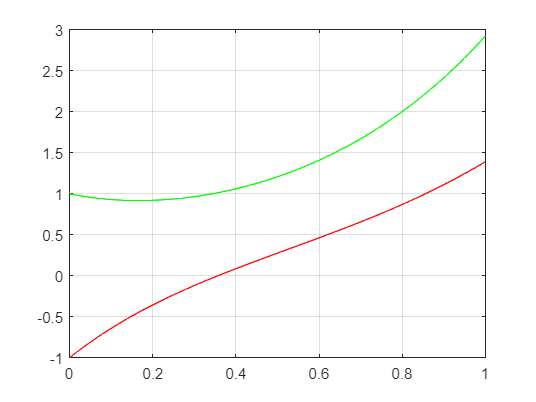

tspan = [0,1];
ybv = [1;-1];
n = 100;
[t, y] = minEuler(@funkEx142, tspan, ybv, n);
clf
plot(t, y(1,:), 'g')
hold on
plot(t,y(2,:), 'r')
grid on
hold off